# Classification And Regression Trees

## Classification And Regression Trees (CART)

The main idea of how **Classification And Regression Trees (CART)** operate is that they partition the feature space into sets of rectangles based on an approximation of Bayes optimal classifier.

To partition the data, we ask a question about one variable, and based on a threshold, we split the dataset by the pre-defined threshold. This operation is performed recursively until each box contains data points mostly from the same class. 

In a classification problem, the final boxes are labelled with the majority class, while in a regression problem, the final value ends up being the mode of the box.

### **Advantages of decision trees:**

- **Computationally inexpensive:              **These algorithms will don't take much resources from the CPU

- **Variable selection:**                                  By determining the best splits, trees will use the most important variables in the  dataset to fit a model

- **Accounts for interactions:**                     Tree methods can handle correlated data really well

- **Automatically handles missing data:**    For categorical data, a new category is made for missing data

- **Can use mixed variable types**:               Trees can use both categorical and numerical data simultaneously

- **No need to transform the data: **             Decisions are made using the range of each variable individually, so there's no need to perform a transformation.

- **Intuitive:**                                                   Trees make decisions in a similar process that humans do.

- **Visualization:**                                           Trees can be visualized, showing the decision process.

- **Hyperparameter tuning is minimal:**       It turns out that the number of hyperparameters to be tuned is negligent. 

### Disadvantages of decision trees:

- **Tree instability:**                                         There is high variance in trees from small perturbations in the training dataset

- **Greedy algorithm:                                    **Estimates local optimum answers as an estimation of the best prediction.

## Anatomy of a decision tree

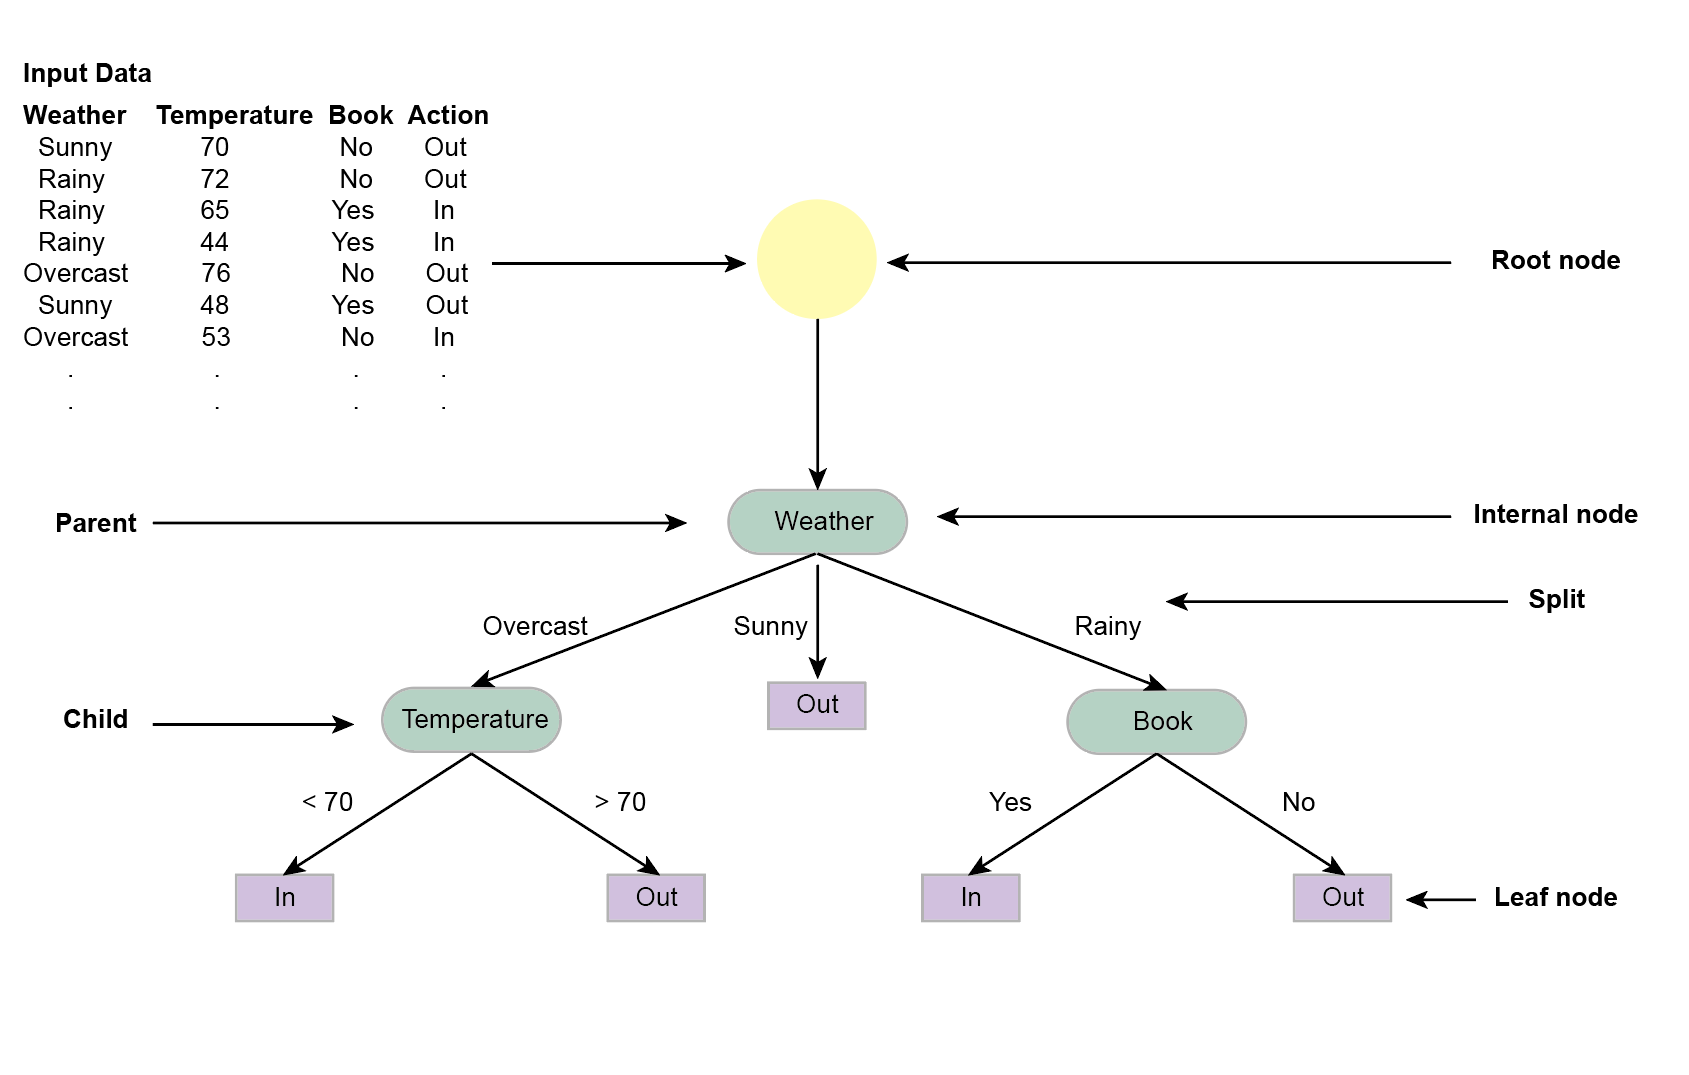

### Physical objects in a tree

**Root node: **The root node represents the entire sample that will be partitioned

**Internal (Decision) node:** Internal nodes within the decision tree are decision points

**Splitting: **Splitting is the process of dividing a node into two or more sub-nodes

**Leaf (Terminal) node: **Nodes that do not split further, such as classification labels

### Relationships between tree objects

**Parent node: **The original node prior to the split

**Child node: **The subnodes after a split

## Intuition in the CART Process

Decision trees are a roadmap that mimicks how we make decisions everyday. Consider the following example, where we are trying to predict whether or not someone is going to leave the house or not. This is based on past information, including the weather, temperature, and if they had have a book or not.

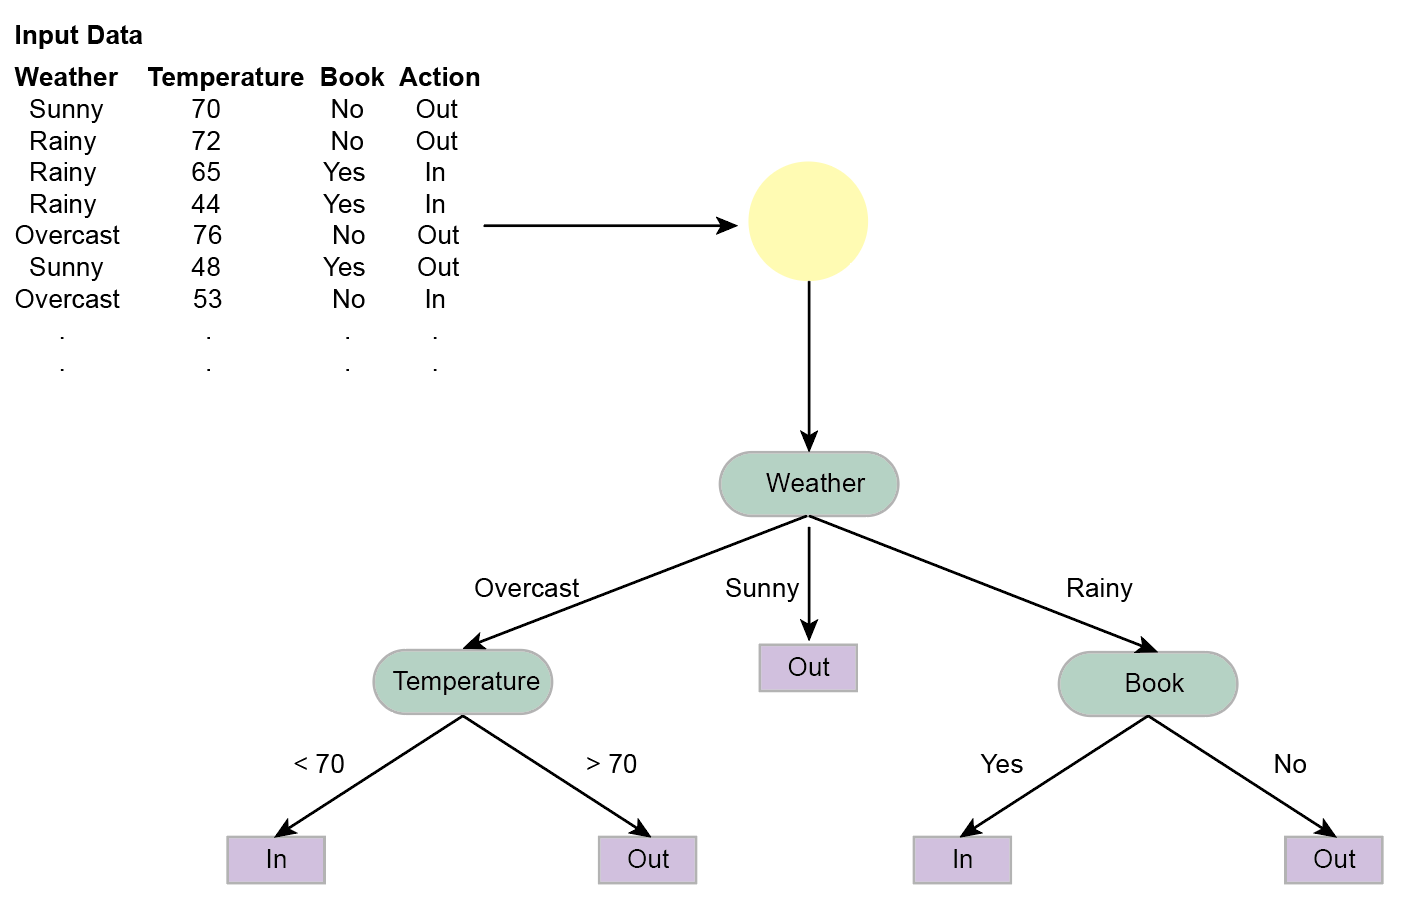

By categorizing the weather and book variables, and using a criterion for continuous data, a decision tree can be constructed to provide the most-likely class, based on their past behavior. Thus, we are drawing decision boundaries with each split, allowing us to perform a final classification based on the decisions we've made when training the model.

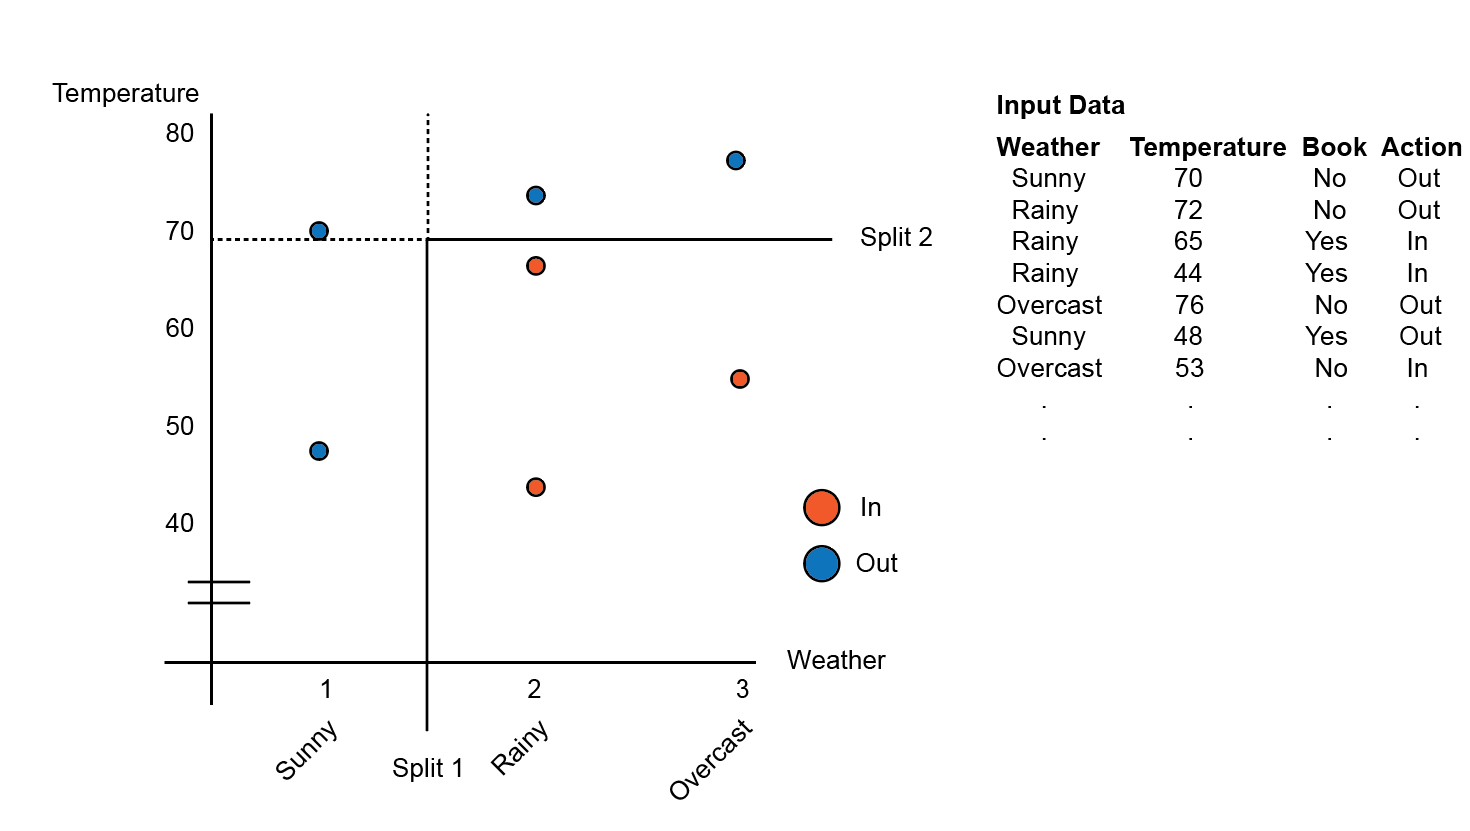

We'll go over the process to build a decision tree in depth in the following sections, and how to solve both regression and classification based problems. However, the basic algorithm for a decision tree is the following:

- Determine the best feature to perform a split on

- Split the data into subsets using a decision rule 

- Repeat the process recursively until we have optimized a balance of maximum accuracy while minimizing the number of splits or nodes.

## Solving a CART

At each decision node, a tree splits the data based on the splitting variables and some criterion to decide whether or not the data point is part of this variable. One key question is, how do we decide which node to split on at any given step? The short answer is we'll choose the feature that can best partition the data. Then we'll repeat this process.

### Choosing which feature to split

#### Intuition

To choose the best feature to split on, we need to see which features can give us the best split. 

For **classification** problems, this is by measuring the proportion of clases for each feature, and by evaluating how well we can partition the data using the **mode** (majority vote). 

For a **regression** problem, the data is split into two parts by the **mean**, and the feature that can best partition the data by the mean will be selected for a split.

#### The objective function

Let's define the number of observations to be $n$, a given node to be $m$, and the entire feature space as $F_{m}$. The proportions of observations $p_{k}$ in a given class $k$ can be defined with the following expression:


$$p_k \left(m\right)=\frac{1}{n_m }\sum_{x_i \;\in {\;F}_m } I\left(y_i =c_k \right)$$


This expression is for a classification problem, and it simply tells us the proportion of observations that belong to a given $k$ class. Thus, when trying to partition the data, we're trying to maximize the proportion of the observation $p_{k}$ for any given class.


$$\hat{k} \left(m\right)=\underset{k}{\mathrm{argmax}} \;p_k \left(m\right)$$


The decision rule a tree makes is to assign node $m$ to the majority class $\hat{k} \left(m\right)$. This ensures that nodes with more homogenous class distributions are preferred.

We have shown that in a classification problem, we want to maximize the proportion of one class over another, and that is our criterion for determining the best split. Now that we have a clear idea of how the decision tree determines how to partition the data, and the objective function of a decision tree, we need define a loss function that measures how wrong, or how impure a node is. In the context of discussing tree-based algorithms, the cost value is known as **node impurity**.

### Node impurity functions

Node impurity is another way of quantifying how well the decision tree partitioned the data. We'll be using a two-class problem with the following distributiuon of 10 observations in nodes $m_1$, $m_2$, and $m_3$ to illustrate how three common methods evaluate node impurity. From the top to the bottom, the nodes become more pure - they have more $A$ or $B$.


$$m_1 = [A, B, B, A, B, A, A, A, B, B]$$



$$m_2 = [A, B, B, B, B, A, A, B, B, B]$$



$$m_3 = [A, A, B, A, B, A, A, A, A, A]$$


#### Gini impurity

For the **Gini impurity score**, we want the score to be low when our node is more pure, and high when our node is impure. Thus, we can create a formulation the measures the impurity as a function of the proportion of classes in the node:


$$\mathrm{Gini}=1-\sum_k p_k^2$$


An intuitive way to think about how pure a node has split two classes $A$ and $B$ is to measure the proportion of $A$ with respect to the entire dataset, and the same for $B$.


$$p_A =\frac{n_A }{n_A +n_B }$$
 


$$p_B =\frac{n_B }{n_A +n_B }$$


For our two-class problem, the Gini impurity score can be computed with the following expression:


$$\textrm{Gini}=1-\left(p_A^2 +p_B^2 \right)$$


Let's compute the Gini impurity score for each node:


$$\begin{array}{l}
m_1 :\;{\textrm{Gini}}_1 =1-\left({0\ldotp 5}^2 +0\ldotp 5^2 \right)=0\ldotp 5\\
m_2 :\;{\textrm{Gini}}_2 =1-\left({0\ldotp 3}^2 +{0\ldotp 7}^2 \right)=0\ldotp 42\\
m_3 :\;{\textrm{Gini}}_3 =1-\left({0\ldotp 8}^2 +{0\ldotp 2}^2 \right)=0\ldotp 32
\end{array}$$


As you can see, the score becomes smaller as we have a higher representation of one class versus another. A Gini score of 0 is the most pure and 0.5 is completely impure.

#### Cross-Entropy 

The **entropy** measure gives us a probabilistic interpretation of the node impurity, as it measures the expected uncertainty associated with a given node.

The $log_2$ function in this formulation gives the score some useful mathematical properties, which are explained below. The entropy measure is shown with the following expression:


$$\mathrm{Entropy}=-\sum_k p_k {\mathrm{log}}_2 p_k$$


Before we dissect entropy further, we need to discuss what it exactly measures - information about the system.

*Information*

Information about an event is encoded in the probability of occurence $p$:


$$\textrm{Information}=\log \left(\frac{1}{p}\right)=-\log \left(p\right)$$


This is for one set events. But how do we measure information for multiple indpendent events? That's where the $log$ comes in. We take the $log$ of the probability, because it has **additive** properties. Thus, if we have two independent variables, the probability of measuring both of these variables is the product of their probability. 

For two classes, we can formulate the overall information class $A$ and $B$ contribute to a particular problem with the following expression:


$$I_A +I_B =\log \left(\frac{1}{p_A }\right)+\log \left(\frac{1}{p_B }\right)=\log \left(\frac{1}{p_A p_B }\right)=\log \left(\frac{1}{P\left(A\;\textrm{and}\;B\right)}\right)$$


*Entropy*

Now that we discussed how information about a given event is computed, let's return to the entropy measure. Given that $p$ is a probability, we have two measures: the event occuring ($p$) and the event not occuring ($1-p$). 

We can measure the entropy of the probability distribution, which is the sum of the information weighted by the probability of the event occurring. In other words, it is the average uncertainty associated with a given set of events.

Note that the $log_2$ is taken for problems where we want to store information as **bits, **or as 0s or 1s (ie a classification problem). The formulation for entropy in our two class problem is


$$\textrm{Entropy}\left(p,1-p\right)=-{\textrm{plog}}_2 p-\left(1-p\right)\log_2 \left(1-p\right)$$


Let's compute the entropy for each node for $A$:


$$\begin{array}{l}
m_1 :\;{\textrm{Entropy}}_1 =-{0\ldotp 5\log }_2 \left(0\ldotp 5\right)-\left(1-0\ldotp 5\right)\log_2 \left(1-0\ldotp 5\right)=1\ldotp 00\\
m_2 :\;{\textrm{Entropy}}_2 =-{0\ldotp 3\log }_2 \left(0\ldotp 3\right)-\left(1-0\ldotp 3\right)\log_2 \left(1-0\ldotp 3\right)=0\ldotp 88\\
m_3 :\;{\textrm{Entropy}}_3 =-{0\ldotp 2\log }_2 \left(0\ldotp 2\right)-\left(1-0\ldotp 2\right)\log_2 \left(1-2\right)\;\;\;\;\;=0\ldotp 72
\end{array}$$


**Thus, the higher the entropy score is, the closer the event is to random**. Similar to the Gini impurity score, entropy assumes a value from 0 to 1, where 0 is the most pure node, while 1 is equivalent to observing a random event. 

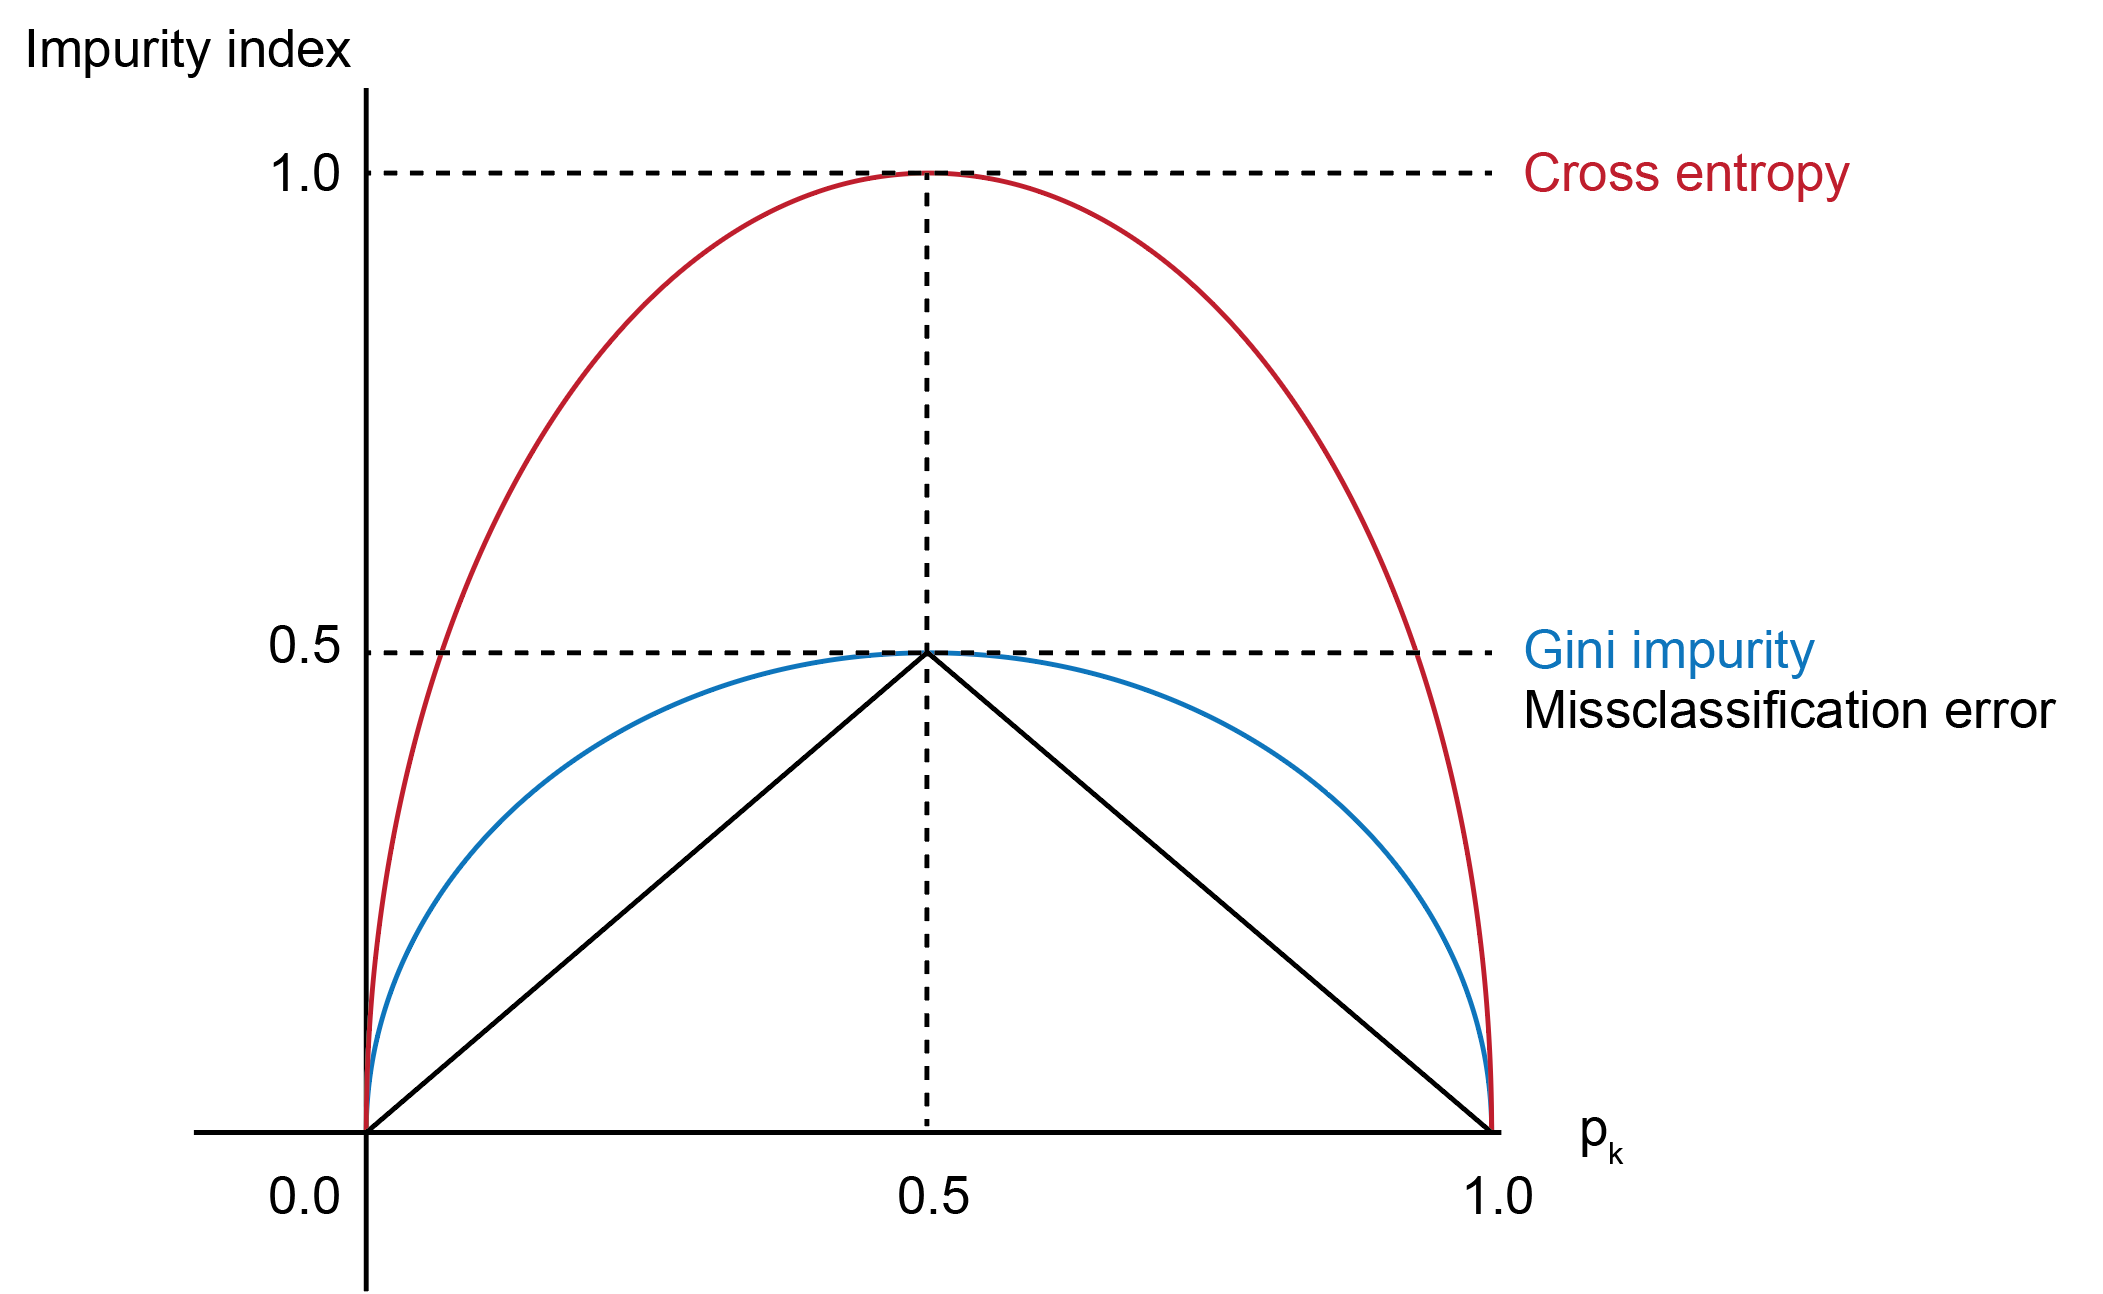

Coming back to how to choose a feature to split on, we will evaluate the the impurity of every single feature, and then choose the feature that has the lowest impurity. Then we'll perform a split and repeat this for each feature. 

Now that we've discussed two ways a decision tree measures the amount of error resulting from a split or information extracted from a split, we need a method to evalute the quality of the split. We'll discuss exactly how to evaluate the quality of the split below

### Evaluating the quality of a split

This process of a parent node splitting into children nodes is evaluated several times using the following measure:


$$Q_{\textrm{split}} =\textrm{Impurity}\left(\textrm{parent}\right)-\left(\frac{N_{\textrm{left}} }{N_{\textrm{parent}} }\textrm{Impurity}\left(\textrm{left}\right)+\frac{N_{\textrm{right}} }{N_{\textrm{parent}} }\textrm{Impurity}\left(\textrm{right}\right)\right)$$


This quality metric $Q_{\mathrm{split}}$ evaluates the average decrease in impurity from the parent node to the child node. Thus, to determine exactly the decision threshold for categorical or continuous variables, we will choose the feature that has a final split with the highest quality measure. 

Now that we have gone over this, you could imagine that some trees are not that informative, and in fact, may contain structures that add noise into the data. Thus, we need a way to control for the amount of noise allowed in the model to prevent overfitting.

### Tree pruning

The tree size is a measure of model complexity - if a tree is too large, it may result in overfitting, while if a tree is too small, it results in model underfitting. So how do we determine the tree size? 

Most algorithms do is they grow a large tree, then they **prune** it.

#### Cost-Complexity Pruning

Given a tuning parameter $c_p$, the goal of this optimization problem is to find a subtree that minimizes the following cost complexity criterion:


$$C\left(T\right)=\sum_{t=1}^{\left|T\right|} N_t \cdot \mathrm{Impurity}\left(t\right)+c_p \cdot \left|T\right|$$


where $C\left(T\right)$ is the cost, $T$ is the tree size, and $N_T$ is the numbe rof nodes within the network Within each leaf node, we'll take the sum of all leaf nodes and the impurity measure at each leaf node to evaluate the model, where are perfect model has a value of 0. 

What happens if $c_p=0$? This will choose the largest tree, and minimize the training error.

How should we choose $c_p$? Cross-validation 

## Main issues in building a classification tree

### Tree instability

Trees have high variance. A small change in the data can result in a different series of splits, and makes interpretation challenging. This is because trees have hierarchical relationships: the effect of an error in a split that is at the top will be propagated to lower splits.

Fortunately, this problem is alleviated using ensemble procedures, such as bagging and boosting.

### Greedy algorithm

Decision trees, by construction, are greedy algorithms. They select optimal choices at each splitting stage, with the aim to find a global optimum. However, these series of local optima may actually not lead to a globally optimal solution, but are good approximations for one.

## CART in MATLAB

dt = fitctree(Xtrain, Ytrain, ...
    'SplitCriterion', 'gdi')      % Impurity measure: Gini

## Summary